# Complex Sine Waves

%general simulation parameters
srate = 500; % Sampling Rate in Hz
time = 0:1/srate:2-1/srate; %time in sec

%Sine Wave Parameters 
freq = 5; 
ampl = 2; 
phas = pi/3;

%Generating the complex sine wave
csw = ampl * exp ( 1i*(2*pi*freq*time + phas))

csw =    1.0000 + 1.7321i   0.8893 + 1.7914i   0.7750 + 1.8437i   0.6577 + 1.8888i   0.5378 + 1.9263i   0.4158 + 1.9563i   0.2922 + 1.9785i   0.1674 + 1.9930i   0.0419 + 1.9996i  -0.0838 + 1.9982i  -0.2091 + 1.9890i  -0.3335 + 1.9720i  -0.4567 + 1.9472i  -0.5781 + 1.9146i  -0.6971 + 1.8746i  -0.8135 + 1.8271i  -0.9266 + 1.7724i  -1.0361 + 1.7107i  -1.1414 + 1.6423i  -1.2423 + 1.5674i  -1.3383 + 1.4863i  -1.4289 + 1.3993i  -1.5140 + 1.3068i  -1.5931 + 1.2092i  -1.6658 + 1.1068i  -1.7321 + 1.0000i  -1.7914 + 0.8893i  -1.8437 + 0.7750i  -1.8888 + 0.6577i  -1.9263 + 0.5378i  -1.9563 + 0.4158i  -1.9785 + 0.2922i  -1.9930 + 0.1674i  -1.9996 + 0.0419i  -1.9982 - 0.0838i  -1.9890 - 0.2091i  -1.9720 - 0.3335i  -1.9472 - 0.4567i  -1.9146 - 0.5781i  -1.8746 - 0.6971i  -1.8271 - 0.8135i  -1.7724 - 0.9266i  -1.7107 - 1.0361i  -1.6423 - 1.1414i  -1.5674 - 1.2423i  -1.4863 - 1.3383i  -1.3993 - 1.4289i  -1.3068 - 1.5140i  -1.2092 - 1.5931i  -1.1068 - 1.6658i


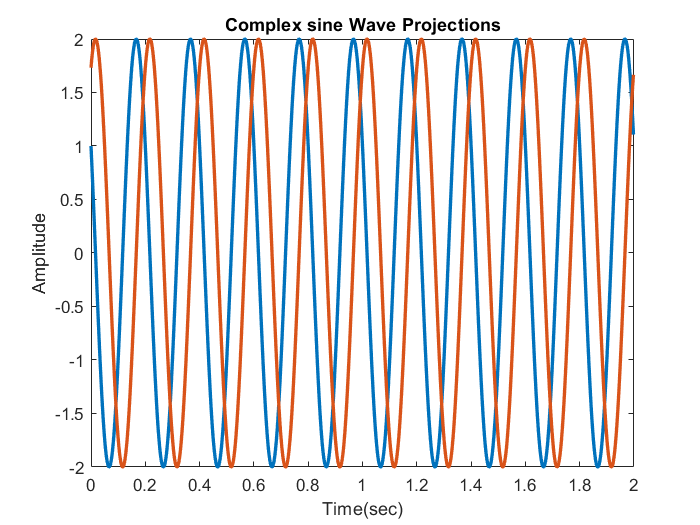

%2D Plot
plot (time, real (csw), time , imag(csw),'linew', 2)
xlabel ('Time(sec)'), ylabel('Amplitude')
title ('Complex sine Wave Projections')

%legend (('real'; 'imag'))

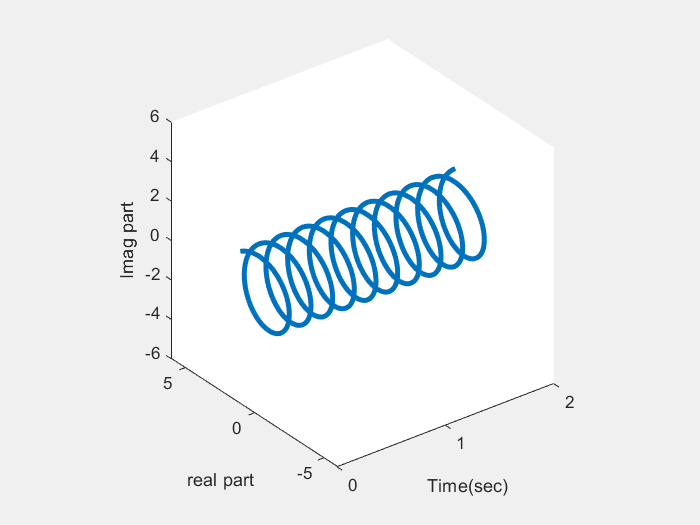

%3D Plot
plot3(time, real(csw),imag(csw),'linew', 3)
xlabel('Time(sec)'), ylabel ('real part'), zlabel('Imag part')
ylim (([-1 1]*ampl*3));
zlim(([-1 1]*ampl*3));
axis square
rotate3d on

%It is more of a spiral/spring